**Load dataset**

if(isempty(which('hosvd')))
    error('Please add tensor toolbox to your path for visualizations.')
end

%% load dataset
folder = fileparts(which('exampleGMLM_DMC_task'));
fname = sprintf('%s/DMC_data/sub_B_data.mat', folder);
load(fname, 'Neurons', 'TaskInfo');

%settings for fitting
GPU_to_use = 0;
gpuDoublePrecision = true;

dim_R_stim_max = 12; % max stimulus rank to consider
dim_R_lev  = 3; %rank of lever filters

%which parts of the trial we will keep (UNITS ARE BINS)
timeBeforeSample     = 0; %time before sample stimulus on that will be include
timeAfterTestOrLever = ceil(50/TaskInfo.binSize_ms); %time after lever release OR test stim off that will be kept

**Setup task and GMLM structure**

Here, we use the full direction tuning model for rank selection (not the cosine-tuned model).

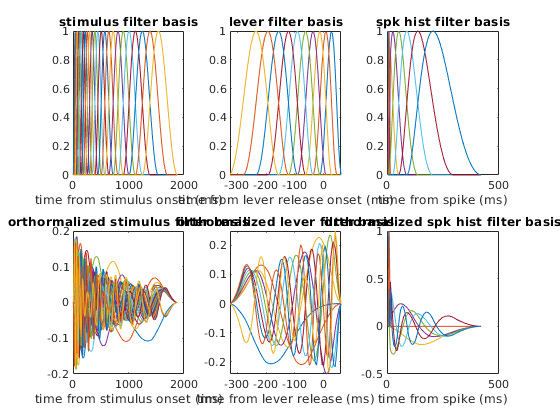

bases = DMC.modelBuilder.setupBasis('bins_post_lever', timeAfterTestOrLever, 'delta_t', TaskInfo.binSize_ms/1e3, 'plotBases', true);

[stimulus_config, stimPrior_setup] = DMC.modelBuilder.getModelSetup(TaskInfo, 'dirTuningType', 'full', 'dirSameSampleTest', true, 'includeCategory', true);

[GMLMstructure, trials] = DMC.modelBuilder.constructGMLMRegressors(Neurons, TaskInfo, stimulus_config, 'timeBeforeSample_bins', timeBeforeSample, 'timeAfterTestOrLever_bins', timeAfterTestOrLever, 'bases', bases);


setting up Neuron 1 / 31
setting up Neuron 2 / 31
setting up Neuron 3 / 31
setting up Neuron 4 / 31
setting up Neuron 5 / 31
setting up Neuron 6 / 31
setting up Neuron 7 / 31
setting up Neuron 8 / 31
setting up Neuron 9 / 31
setting up Neuron 10 / 31
setting up Neuron 11 / 31
setting up Neuron 12 / 31
setting up Neuron 13 / 31
setting up Neuron 14 / 31
setting up Neuron 15 / 31
setting up Neuron 16 / 31
setting up Neuron 17 / 31
setting up Neuron 18 / 31
setting up Neuron 19 / 31
setting up Neuron 20 / 31
setting up Neuron 21 / 31
setting up Neuron 22 / 31
setting up Neuron 23 / 31
setting up Neuron 24 / 31
setting up Neuron 25 / 31
setting up Neuron 26 / 31
setting up Neuron 27 / 31
setting up Neuron 28 / 31
setting up Neuron 29 / 31
setting up Neuron 30 / 31
setting up Neuron 31 / 31
Done setting up data


[prior_function_stim, prior_function_lever, prior_function_spkHist, ~, levPrior_setup, spkHistPrior_setup] = DMC.modelBuilder.setupPriorFunctions(stimPrior_setup, bases);

GMLMstructure.prior.dim_H          = spkHistPrior_setup.NH;
GMLMstructure.prior.log_prior_func = prior_function_spkHist;

GMLMstructure.Groups(1).prior.dim_H          = stimPrior_setup.NH;
GMLMstructure.Groups(1).prior.log_prior_func = prior_function_stim;
GMLMstructure.Groups(1).dim_R_max = dim_R_stim_max;

GMLMstructure.Groups(2).prior.dim_H          = levPrior_setup.NH;
GMLMstructure.Groups(2).prior.log_prior_func = prior_function_lever;
GMLMstructure.Groups(2).dim_R_max = dim_R_lev;

gmlm = kgmlm.GMLM(GMLMstructure, trials, TaskInfo.binSize_ms./1e3);

**Setup cross validation**

Cross-validation is performed on folds over trials (not individual bins). I setup the folds to evenly divide trials over neurons and sample directions (it would be bad for fitting if a fold had 0 trials for a neuron on a particular direction in the full-tuning model!).

K = 10; %K-fold CV
ctr = 0;
trialNeuronSampleDir_ids = nan(gmlm.dim_M, 1); %for dividing up trials evenly by sample direction and neuron
for ii = 1:numel(Neurons)
    trialNeuronSampleDir_ids(ctr + (1:numel(Neurons(ii).sampleDir))) = Neurons(ii).sampleDir + ii*100;
    ctr = ctr + numel(Neurons(ii).sampleDir);
end
cvInds =  crossvalind('KFold', trialNeuronSampleDir_ids, K);
cvNeurons = (trialNeuronSampleDir_ids - mod(trialNeuronSampleDir_ids, 100))/100; %neuron number of each trial in the fold setup

**Fit the GLM to each neuron**

The GLM represents the "full-rank" model to asses how well the low-rank models fit the data.

Fitting is done using cross-validated performance of a MAP estimate. The hyperparameters for each fold are selected using evidence optimization.

glm_fits_xv = struct('Ks', cell(K, numel(Neurons)), 'H', [], 'group_names', []);
glm_LL_xv   = struct('trialLL_train', cell(1, numel(Neurons)), 'trialLL_test', []);

for nn = 1:numel(Neurons) %note: this step may be parallelized over cells (multiple GPUs with multiple cells per GPU)
    fprintf('GLM cell %d / %d\n', nn, numel(Neurons));
    
    %setup GLM
    [GLMstructure, trials_c] = DMC.modelBuilder.constructGLMdesignMatrix(Neurons, TaskInfo, nn, stimulus_config, 'timeBeforeSample_bins', timeBeforeSample, 'bins_post_lever', timeAfterTestOrLever, 'bases', bases);

    [~, ~, ~, prior_function_glmComplete, levPrior_setup, spkHistPrior_setup] = DMC.modelBuilder.setupPriorFunctions(stimPrior_setup, bases);

    GLMstructure.prior.dim_H          = stimPrior_setup.NH + levPrior_setup.NH + spkHistPrior_setup.NH;
    GLMstructure.prior.log_prior_func = prior_function_glmComplete;
    
    glm = kgmlm.kcGLM(GLMstructure, trials_c, TaskInfo.binSize_ms./1e3);
    glm.toGPU(GPU_to_use, 'useDoublePrecision', gpuDoublePrecision);
    
    %fit with CV
    [glm_fits_xv(:, nn), results_test_xv, results_train_xv] = glm.computeMAPevidenceOptimization_crossValidated(cvInds(cvNeurons == nn), 'fitAll', false);
    
    glm_LL_xv(nn).trialLL_train = [results_train_xv(:).trialLL];
    glm_LL_xv(nn).trialLL_test  = [results_test_xv(:).trialLL];
    
    %unload GLM from GPU
    glm.freeGPU();
end

GLM cell 1 / 31


Parsing data from cell 1... done.


GLM destructor: clearing GLM from GPU.


Fitting fold 1 / 10...
Fitting fold 2 / 10...
Fitting fold 3 / 10...
Fitting fold 4 / 10...
Fitting fold 5 / 10...
Fitting fold 6 / 10...
Fitting fold 7 / 10...
Fitting fold 8 / 10...
Fitting fold 9 / 10...
Fitting fold 10 / 10...


fprintf('GLMs complete.\n');

**Fit the GMLM for each rank of the stimulus filter tensor**

Starts with the rank 0 model, which has no stimulus tuning. This gives the performance floor (what is explained by the constant rate, spike history filter, and touch-bar release filter).

%% GMLM fits: for each rank - fit GMLM to population and get x-val performance
dim_Rs = 1:dim_R_stim_max; %ranks of stim filter to test

%setup GMLM
gmlm.toGPU(GPU_to_use, 'useDoublePrecision', gpuDoublePrecision);

%fit model without stimulus terms (rank 0 model)
gmlm.setDimR('Stimulus', 0);
[gmlm_rank0_fit, results_test_mle_cv, results_train_mle_cv] = gmlm.computeMLE_crossValidated(cvInds);
gmlm_rank0_LL_xv.trialLL_test  = [results_test_mle_cv(:).trialLL];
gmlm_rank0_LL_xv.trialLL_train = [results_train_mle_cv(:).trialLL];

%for each rank
gmlm_fits_xv = struct('W', cell(K, numel(dim_Rs)), 'H', [], 'B', [], 'Groups', []);
gmlm_LL_xv   = struct('trialLL_train', cell(1, numel(dim_Rs)), 'trialLL_test', []);
for rr_idx = 1:numel(dim_Rs)
    fprintf('GMLM rank %d (%d / %d)\n', dim_Rs(rr_idx), nn, numel(Neurons));
    
    %set rank
    dim_R = dim_Rs(rr_idx);
    gmlm.setDimR('Stimulus', dim_R);
    
    %fit population with CV
        %note: with dim_R > 1, we can use the fits from the previous rank plus another stim component tacked on as an init point if we want (not done here).
    msgStr            = sprintf('MLE, stimulus rank = %d', gmlm.getGroupRank('stimulus'));
    [gmlm_fits_xv(:, rr_idx), results_test_mle_cv, results_train_mle_cv, params_init_cv] = gmlm.computeMLE_crossValidated(cvInds, 'fitAll', false);
    gmlm_LL_xv(rr_idx).trialLL_test  = [results_test_mle_cv(:).trialLL];
    gmlm_LL_xv(rr_idx).trialLL_train = [results_train_mle_cv(:).trialLL];
end

%unload from GPU
gmlm.freeGPU();
fprintf('GMLMs complete.\n');

**Plot rank selection summary**

Gets the mean log-likehood per trial explained by each rank. This is then normalized by the rank 0 model and the GLM.

perTrial_ll_glm  = nan(numel(Neurons), 1); %per neuron cross-validated log like per trial (full rank model)
perTrial_ll_gmlm = nan(numel(Neurons), numel(dim_Rs)); 
perTrial_ll_gmlm_rank0 = nan(numel(Neurons), 1); 

neuronNumPerTrial = [trials(:).neuron]';

for nn = 1:numel(Neurons)
    perTrial_ll_glm(nn) = nanmean(glm_LL_xv(nn).trialLL_test, 'all');
    
    trialsForCurrentNeuron = neuronNumPerTrial == nn;
    perTrial_ll_gmlm_rank0(nn) = nanmean(gmlm_rank0_LL_xv.trialLL_test(trialsForCurrentNeuron, :), 'all');
    for rr = 1:numel(dim_Rs)
        if(~isempty(gmlm_LL_xv(rr).trialLL_test))
            perTrial_ll_gmlm(nn, rr) = nanmean(gmlm_LL_xv(rr).trialLL_test(trialsForCurrentNeuron, :), 'all');
        end
    end
end

mean_perTrial_ll_glm  = mean(perTrial_ll_glm);
mean_perTrial_ll_gmlm_rank0  = mean(perTrial_ll_gmlm_rank0);
mean_perTrial_ll_gmlm = mean(perTrial_ll_gmlm, 1);

normalized_perTrial_ll_gmlm = (mean_perTrial_ll_gmlm - mean_perTrial_ll_gmlm_rank0) ./ (mean_perTrial_ll_glm - mean_perTrial_ll_gmlm_rank0);

thresholdForRankSelection = 0.9; %model should account for 90% of log likelihood possible

figure(1);
clf
subplot(1,2,1);
hold on
plot([0 dim_Rs], [mean_perTrial_ll_gmlm_rank0 mean_perTrial_ll_gmlm], 'o-');
plot([0 dim_Rs(end)], [1 1]*mean_perTrial_ll_glm, 'k-');
ylabel('mean log like per trial');
xlabel('GMLM stimulus rank');

subplot(1,2,2);
hold on
plot(dim_Rs, normalized_perTrial_ll_gmlm, 'o-');
plot([dim_Rs(1) dim_Rs(end)], [1 1]*thresholdForRankSelection, 'k:'); %plot threshold for rank selection
ylabel('frac. of log like');
xlabel('GMLM stimulus rank');
ylim([0 1]);

mm = find(normalized_perTrial_ll_gmlm > thresholdForRankSelection, 1, 'first');
if(isempty(mm))
    dim_R_selected = nan;
    fprintf('No rank used met the selection threshold.\n');
else
    dim_R_selected = dim_Rs(mm);
    fprintf('Model with rank %d met the selection threshold.\n', dim_R_selected);
end

**MCMC inference for the MAP esimate of the full model**

Uses the rank selected for the stimulus

gmlm.setDimR('Stimulus', dim_R_selected);

% run HMC
HMC_settings = gmlm.setupHMCparams();
params_init  = gmlm.getRandomParamStruct();
[samples, summary, HMC_settings, params_final, M] = gmlm.runHMC_simple( params_init, HMC_settings, "figure", 10);

% get posterior median hyperparams
params_final.H(:) = median(samples.H(:,(HMC_settings.nWarmup+1):end),2);
for jj = 1:gmlm.dim_J
    params_final.Groups(jj).H(:) = median(samples.Groups(jj).H(:,(HMC_settings.nWarmup+1):end), 2);
end

% get MAP
[params_map, results_map] = gmlm.computeMAP(params_final);

% clear from GPU
gmlm.freeGPU();

% plot model fit
DMC.plottingTools.plotGMLMFit(TaskInfo, params_map, bases, stimulus_config(:,:,1));


**MCMC inference of cosine-tuned model for the selected rank**

% setup cosine-tuned GMLM
[stimulus_config_cos, stimPrior_setup_cos] = DMC.modelBuilder.getModelSetup(TaskInfo, 'dirTuningType', 'full', 'dirSameSampleTest', true, 'includeCategory', true);
[GMLMstructure_cos, trials] = DMC.modelBuilder.constructGMLMRegressors(Neurons, TaskInfo, timeBeforeSample, timeAfterTestOrLever, bases, stimulus_config);

prior_function_stim_cos = DMC.modelBuilder.setupPriorFunctions(stimPrior_setup_cos, bases);

GMLMstructure_cos.prior.dim_H          = spkHistPrior_setup.NH;
GMLMstructure_cos.prior.log_prior_func = prior_function_spkHist;

GMLMstructure_cos.Groups(1).prior.dim_H          = stimPrior_setup_cos.NH;
GMLMstructure_cos.Groups(1).prior.log_prior_func = prior_function_stim_cos;
GMLMstructure_cos.Groups(1).dim_R_max = dim_R_stim_max;

GMLMstructure_cos.Groups(2).prior.dim_H          = levPrior_setup.NH;
GMLMstructure_cos.Groups(2).prior.log_prior_func = prior_function_lever;
GMLMstructure_cos.Groups(2).dim_R_max = dim_R_lev;

gmlm_cos = kgmlm.GMLM(GMLMstructure_cos, trials, TaskInfo.binSize_ms./1e3);
gmlm_cos.setDimR('Stimulus', dim_R_selected);

% send to GPU
gmlm_cos.toGPU(GPU_to_use, 'useDoublePrecision', gpuDoublePrecision);

% run HMC
HMC_settings = gmlm.setupHMCparams();
params_init  = gmlm.getRandomParamStruct();
[samples_cos, summary_cos] = gmlm.runHMC_simple( params_init, HMC_settings, "figure", 11);

% clear from GPU
gmlm_cos.freeGPU();

% get category and direction tuning statistics
[filtStats, timePeriods, timeInfo] = DMC.analysis.computeCosineSubspaceMetrics(samples_cos, HMC_settings, bases, TaskInfo.binSize_ms/1e3);

**Plot results**

figure(12);
clf;

lw_1 = 1;
ls = '-';


%sample cat and direction tuning vector norms
ax1 = subplot(3, 3, 1:3);
hold(ax1,"on")

CI = 99; % which credible region to use (only pre-computed percentile ranges will work)
pp = (100-CI)/2;
mdLine    =  find(filtStats.prcTiles == 50, 1);
errLines  = [find(filtStats.prcTiles == pp, 1) find(filtStats.prcTiles == 100-pp, 1)];
if(numel(errLines) ~= 2)
    error('invalid CI (must be pre-computed)');
end

tt_idx = 0 <= timeInfo.stimBasis_ms & 1500 >= timeInfo.stimBasis_ms;
tts    = timeInfo.stimBasis_ms(tt_idx);
tts = tts(:);
mh = max(filtStats.dir.major_norm(tt_idx, errLines(2)));
mh = max(mh, max(filtStats.dir.minor_norm( tt_idx, errLines(2))));
mh = max(mh, max(filtStats.cat.sample_norm(tt_idx, errLines(2))));
mh = max(mh, max(filtStats.cat.test_norm(tt_idx, errLines(2))));
mh = ceil(mh*10)/10;

DMC.plottingTools.plotRegionForStimulus(ax1, 0, TaskInfo.StimLength_ms, 0, mh);


%plot major axis norm
color_c = [hex2dec('c3') hex2dec('60') hex2dec('01')]./255;
eb1 = filtStats.dir.major_norm(tt_idx, errLines(1));
eb2 = filtStats.dir.major_norm(tt_idx, errLines(2));
yy = filtStats.dir.major_norm(tt_idx, mdLine);
DMC.plottingTools.plotLineWithErrorRegion(ax1, tts, yy, eb1, eb2, color_c, lw_1, ls);

%plot minor axis norm
color_c = [hex2dec('2c') hex2dec('6d') hex2dec('0d')]./255;
eb1 = filtStats.dir.minor_norm(tt_idx, errLines(1));
eb2 = filtStats.dir.minor_norm(tt_idx, errLines(2));
yy = filtStats.dir.minor_norm(tt_idx, mdLine);
DMC.plottingTools.plotLineWithErrorRegion(ax1, tts, yy, eb1, eb2, color_c, lw_1, ls);

%plot cat norm
color_c = [0 0 0];
eb1 = filtStats.cat.sample_norm(tt_idx, errLines(1));
eb2 = filtStats.cat.sample_norm(tt_idx, errLines(2));
yy = filtStats.cat.sample_norm(tt_idx, mdLine);
DMC.plottingTools.plotLineWithErrorRegion(ax1, tts, yy, eb1, eb2, color_c, lw_1, ls);

legObjs = {'dir. major axis', 'dir. minor axis', 'cat. vector'};
    legend(ax1, legObjs, 'location', 'northeast');
xlim(ax1, [tts(1) tts(end)])
ylim(ax1, [0 mh])
xlabel(ax1, 'time from sample onset (ms)')
ylabel(ax1, 'vector norm')


%sample cat and direction tuning vector norms
ax2 = subplot(3, 3, 4:5);
hold(ax2,"on")

tt_idx = 0 <= timeInfo.stimBasis_ms & 700 >= timeInfo.stimBasis_ms;
tts    = timeInfo.stimBasis_ms(tt_idx);
tts = tts(:);

DMC.plottingTools.plotRegionForStimulus(ax2, 0, TaskInfo.StimLength_ms, 0, mh);

%plot sample cat norm
color_c = [0 0 0];
eb1 = filtStats.cat.sample_norm(tt_idx, errLines(1));
eb2 = filtStats.cat.sample_norm(tt_idx, errLines(2));
yy = filtStats.cat.sample_norm(tt_idx, mdLine);
DMC.plottingTools.plotLineWithErrorRegion(ax2, tts, yy, eb1, eb2, color_c, lw_1, ls);

%plot test cat norm
color_c = [hex2dec('a4') hex2dec('07') hex2dec('78')]./255;
eb1 = filtStats.cat.test_norm(tt_idx, errLines(1));
eb2 = filtStats.cat.test_norm(tt_idx, errLines(2));
yy = filtStats.cat.test_norm(tt_idx, mdLine);
DMC.plottingTools.plotLineWithErrorRegion(ax2, tts, yy, eb1, eb2, color_c, lw_1, ls);

legObjs = {'sample cat. vector', 'test cat. vector'};
    legend(ax2, legObjs, 'location', 'northeast');
xlim(ax2, [tts(1) tts(end)])
ylim(ax2, [0 mh])
xlabel(ax2, 'time from stimulus onset (ms)')
ylabel(ax2, 'vector norm')


%plot prefered direction region
ax3 = subplot(3, 3, 7);

majorAxisColors =  [hex2dec('c3') hex2dec('60') hex2dec('01')]./255;
color_region = [0 0 1;
                1 0 0;
                0.4 0.4 0.4];
hold(ax3,"on")

TimePeriodToUse = 3;

angle_summary = prctile(filtStats.dir.major_angle_minus135_means, filtStats.prcTiles, 2);
    
major_dir    = angle_summary(TimePeriodToUse, mdLine)   + 135;
major_dir_eb = angle_summary(TimePeriodToUse, errLines)   + 135;

DMC.plottingTools.plotHemifield(ax3, major_dir, major_dir_eb, majorAxisColors, color_region);
DMC.plottingTools.plotVectors(ax3, TaskInfo.Directions, DMC.plottingTools.getDirColors_oneBoundaryTask(TaskInfo.Directions), true);
title(ax3, 'direction tuning major axis alignment')